This examples shows the usage of loopsyn

s = tf('s');
G = (-s+10)/(s+3)/(s+4)*exp(-.01*s);
wc = 1;
N = 1;
while(N<2)
    [K,CL,GAM] = loopsyn(pade(G,5),wc/s); %G: plant Gd: target loop shape 5:how much expand
    wc = wc+0.5;
    N = norm(1-CL,'inf');
end

Now check the performance of the design

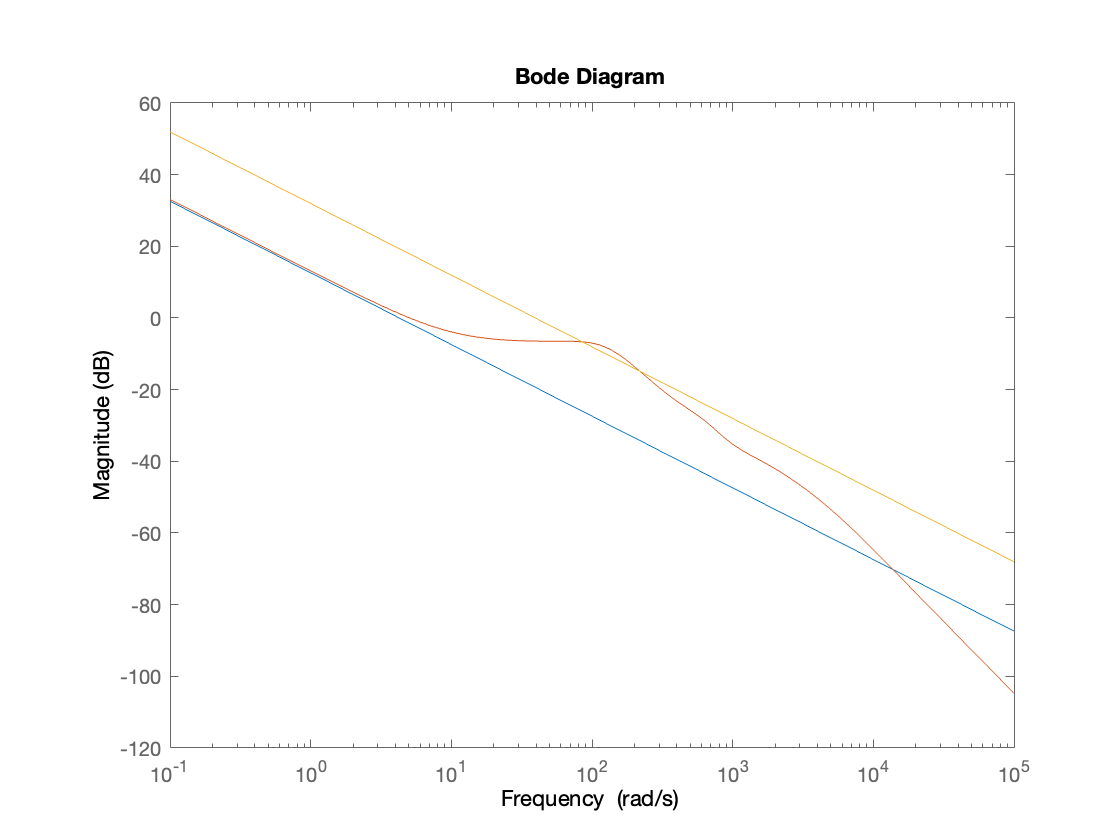

bodemag((wc-0.5)/s/GAM,G*K,(wc-0.5)/s*GAM)

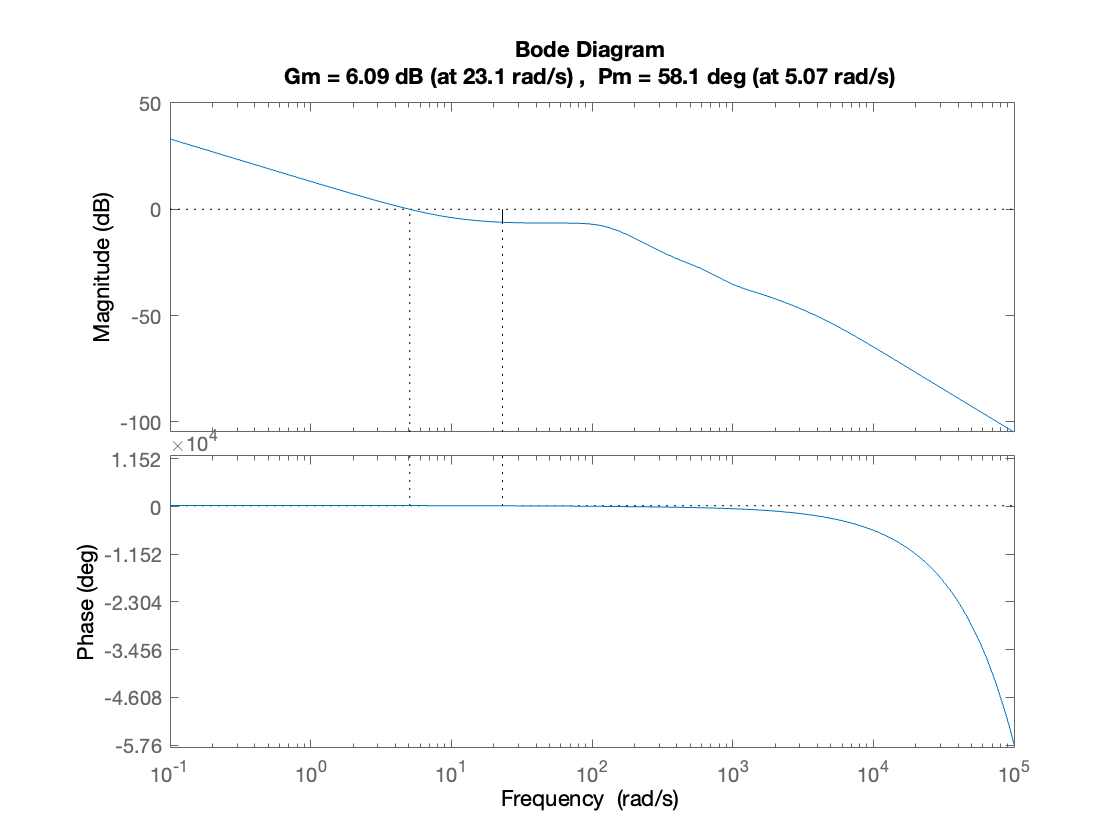

margin(G*K)

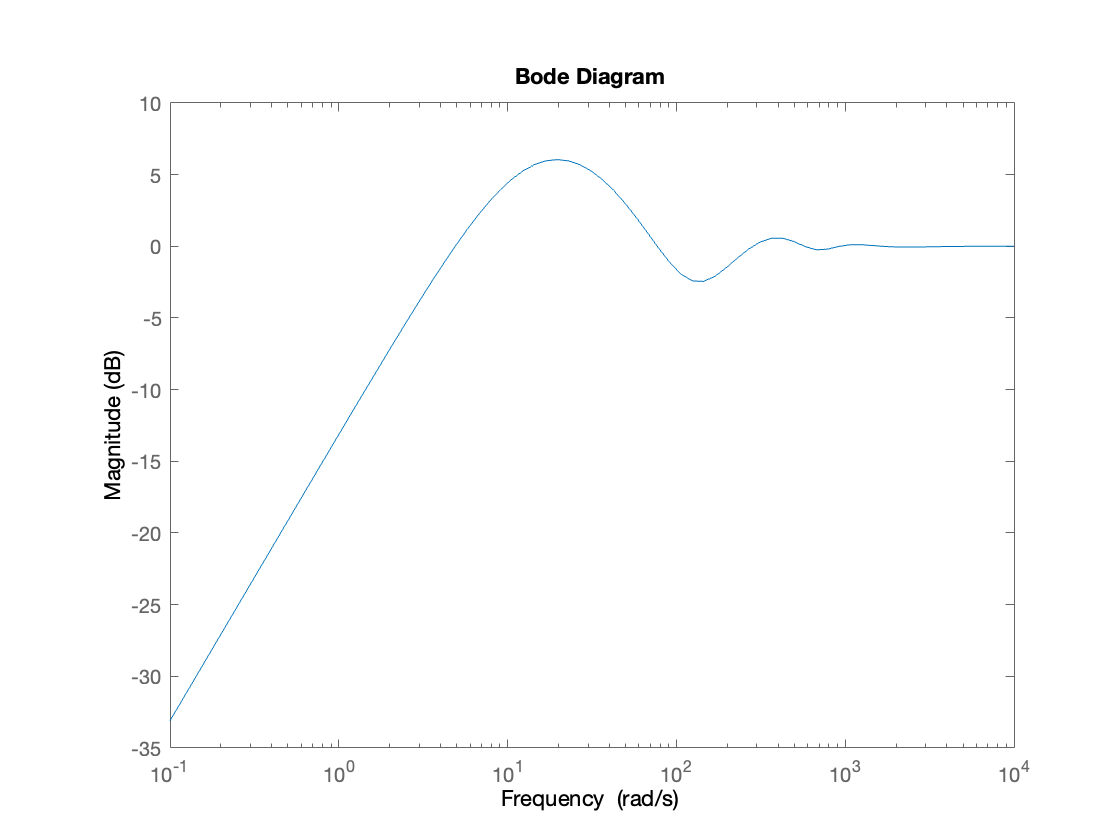

bodemag(1-CL) %sensitivity function